# Estimate a continuous-time transfer function from a step response

The first part of this script carries out the same steps as plotStepResponses.mlx.

## Read and plot the recorded data

The filename below belongs to the file with the step response experiment data. The step response data was recorded for an input step of 5 degrees. This value is fixed in the microcontroller code for the step response experiment, and it needs to be set here by hand. We also need to copy the time step (5ms= 0.05s) used in the arduino sketch. 

clear all;
close all; 
filename= "../../step002-open-loop-step-response/arduino/record_open_loop_step_response_data_for_matlab/data_for_matlab.txt"; 
uStep= 5; % deg, degrees
delta_t= 0.005; % seconds

We are now ready to read the data and to extract the time points and output values from it.

data = readtable(filename); 
tData = data{:, 1}'; % note transpose operator
yData = data{:, 2}';
t0= tData(1);
numpoints= length(yData);

We need to divide all time data by 1e6 to to convert microseconds to seconds. 

tData= tData* 1e-6; 

We first plot the entire set of recorded data, which contains more than one step response. 

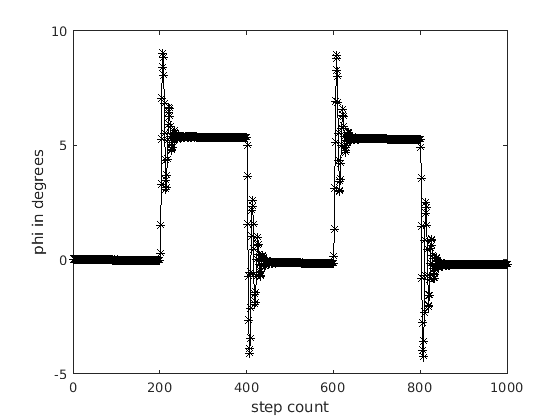

figure(); 
plot(yData, '-*', 'Color', 'black'); 
xlabel("step count");
ylabel("phi in degrees"); 

We now select a single step response to work with. Since the arduino generates a step input every 200 timesteps (which corresponds to a second for the sample time of 5ms), we can select steps 200 to 400. Actually, 200 to 300 suffice, since a new steady state has been reached after 100 steps. Play with these numbers to check if we picked a good interval. (Try 195 to 250, for example. Also try 199 to 250 and 201 to 250.)

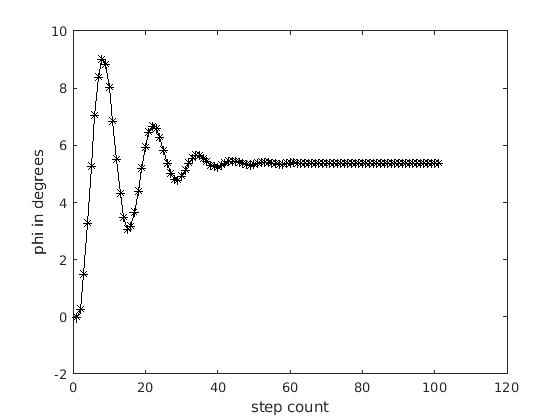

kstart= 200;
kstop= 300; 
figure();
plot(yData(kstart:kstop), '-*', 'Color', 'black'); 
xlabel("step count"); 
ylabel("phi in degrees"); 

Having selected an appropriate interval of steps, we can discard all other data. We can also reset the time of the first data point to be t=0s.

Let's also include the input signal for comparison.

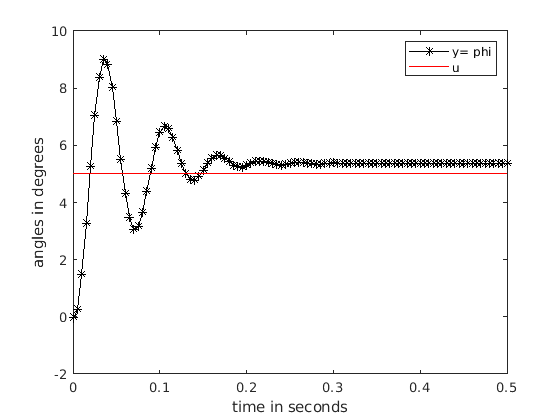

figure(); 
tData= tData(kstart:kstop)- tData(kstart); 
yData= yData(kstart:kstop); 
plot(tData, yData, '-*', 'Color', 'black');
hold on;
uData= uStep* ones(1, length(tData)); 
plot(tData, uData, '-', 'Color', 'red'); 
legend("y= phi", "u"); 
xlabel("time in seconds"); 
ylabel("angles in degrees"); 

## Identification 

identData= iddata(yData', uData', delta_t); 
continuousTimeTransferFunction= tfest(identData, 2, 0);  

[ySim, tSim, xSim]= step(continuousTimeTransferFunction, tData(end)); 

figure(); 
figTitle= "state space model, \phi and integrated \omega";
title(figTitle);
hold on; 
plot(tSim, ySim* uStep);

Let's plot the open-loop step response also by simulating the state space model. There is a built-in matlab command (tf2ss) that converts the transfer function into a state-space model. Here, we carry out this transformation by hand, because it is instructive. Moreover, the conversion does not yield a unique result and, therefore, we have better control over the transformation, if we carry it out by hand:

The transfer function has the form

 
$$\[
G(s)= \frac{K_S}{s^2+ a_1 s+ a_0}
\]$$


and, according to the course notes, this transfer function can be transformed into the state-space model


$$\pmatrix{\dot\varphi \cr \dot\omega}=
\pmatrix{0 & 1 \cr -a_0 & -a_1} \pmatrix{\varphi \cr \omega}+
\pmatrix{0 \cr K_S} u, \quad
y= (1\, 0)\pmatrix{\varphi \cr \omega}
$$


with state vector $x= \pmatrix{\varphi \cr \omega}$. The matrices $A, B, C, D$ for the standard notation

$\dot x= Ax+ Bu, \quad y=Cx+Du
$ are introduced in the next code section:

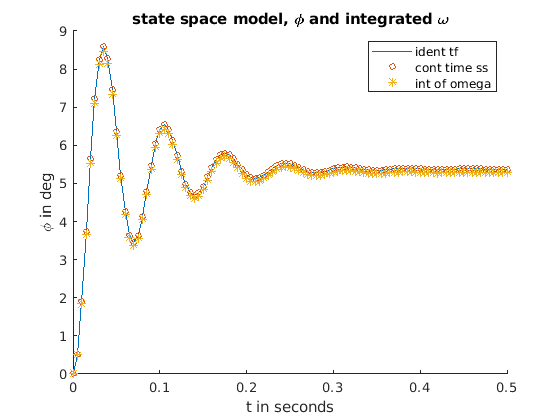

a1= continuousTimeTransferFunction.denom(2);
a0= continuousTimeTransferFunction.denom(3);
KS= continuousTimeTransferFunction.numer(1);
continuousTimeStateSpaceSys.A= [0 1; -a0 -a1];
continuousTimeStateSpaceSys.B= [0; KS];
continuousTimeStateSpaceSys.C= [1 0];
continuousTimeStateSpaceSys.D= 0; 
%[A, B, C, D]= tf2ss(sys.num, sys.denom);
tGridTmp= 0:delta_t:tSim(end);
uStepTimeSeriesTmp= uStep* ones(length(tGridTmp), 1);
[angleOut, tOutTmp, xOutTmp]= lsim(ss(continuousTimeStateSpaceSys.A, continuousTimeStateSpaceSys.B, continuousTimeStateSpaceSys.C, continuousTimeStateSpaceSys.D), uStepTimeSeriesTmp, tGridTmp, [0 0]);

plot(tOutTmp, angleOut, "o", 'MarkerSize', 5); 
xlabel('t in seconds');
ylabel('\phi in deg'); 
% figure();
% plot(tOutTmp, xOutTmp(:,2));
phiFromOmega= zeros(length(tOutTmp), 1);
for k= 2:length(tOutTmp)
    phiFromOmega(k)= phiFromOmega(k-1)+ 0.5*(xOutTmp(k-1, 2)+ xOutTmp(k, 2))* (tOutTmp(k)- tOutTmp(k-1)); 
end
plot(tOutTmp, phiFromOmega, '*'); 
legend('ident tf', 'cont time ss', 'int of omega')
hold off;

Finally, let's compare the model and the experimental data.

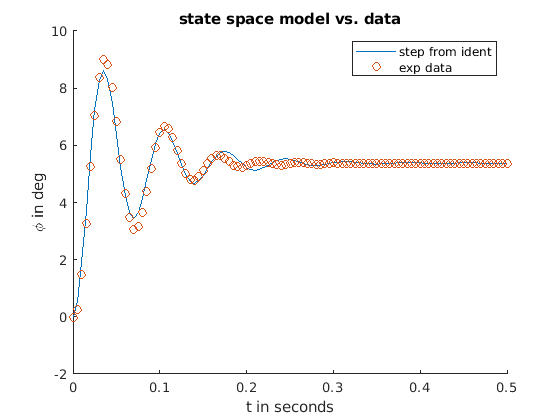

figure(); 
figTitle= "state space model vs. data";
title(figTitle);
hold on; 
plot(tSim, ySim* uStep);
%shifted_tData= tData(ktStep:end)- tData(ktStep);
%shifted_yDeg= yDeg(ktStep:end);
plot(tData, yData, 'o');
xlabel('t in seconds');
ylabel('\phi in deg'); 
legend('step from ident', 'exp data');
hold off; 

## Let's also plot omega for later use (comparison to discrete-time results)

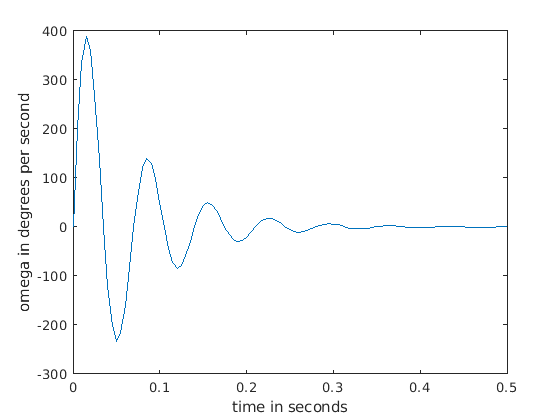

figure(); 
plot(tOutTmp, xOutTmp(:,2));
xlabel('time in seconds');
ylabel('omega in degrees per second');

## Pole placement for state feedback 

K= place(continuousTimeStateSpaceSys.A, continuousTimeStateSpaceSys.B, [-11 -10]);

We cannot yet implement this state feedback, since we only measure one of the two states (the angular velocity, but not the angle itself). We need to design an observer below to determine the missing angle information. Before we do so, let us assume we could implement the controller and check what a step response of the closed-loop system for a 5 degree input step would look like.

% determine closed-loop transfer function (input reference value for angle,
% output actual angle)
[NumerClosed, DenomClosed]= ss2tf(continuousTimeStateSpaceSys.A-continuousTimeStateSpaceSys.B*K, continuousTimeStateSpaceSys.B, continuousTimeStateSpaceSys.C, continuousTimeStateSpaceSys.D);
Gclosed= tf(NumerClosed, DenomClosed);

%
% plot closed-loop step response with prefactor
%
figure();
figTitle= "simulated closed-loop step response";
title(figTitle);
xlabel("time in seconds");
ylabel("phi in degrees"); 
hold on; 
[ySimClosed, tSimClosed]= step(Gclosed);
Bref= 1/ ySimClosed(end); % input matrix (1x1 matrix here) for scaling the reference input
plot(tSimClosed, ySimClosed*Bref*uStep); % instead of multiplying step by Bref we can multiply output, since the system is linear

Just to be safe, let's compare the last result to the result computed with the time-domain system.

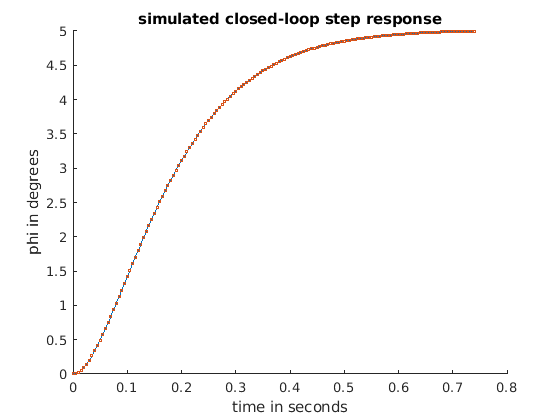

tGridTmp= 0:delta_t:tSimClosed(end); 
uStepTimeSeriesTmp= uStep* Bref* ones(length(tGridTmp), 1);
[angleOut, tOutTmp]= lsim(ss(continuousTimeStateSpaceSys.A-continuousTimeStateSpaceSys.B*K, continuousTimeStateSpaceSys.B, continuousTimeStateSpaceSys.C, continuousTimeStateSpaceSys.D), uStepTimeSeriesTmp, tGridTmp, [0 0]);
plot(tOutTmp, angleOut, "o", 'MarkerSize', 2); 
hold off; 

## State feedback with observer, continuous time, perfect model

Since we cannot measure both states, but only the angular velocity, we have to design an observer in order to be able to use the state feedback. 

Note that our model has the angle as its output. In order to design an observer for the angular velocity, we have to change the output matrix C so as to turn the angular velocity into the output.

Ltransposed= place(continuousTimeStateSpaceSys.A', continuousTimeStateSpaceSys.C', [-101 -100]);
L= Ltransposed'; 

It is convenient to define a system that contains both the simulated system and the observer. This can be done as follows.

Asim = [ continuousTimeStateSpaceSys.A- continuousTimeStateSpaceSys.B* K             continuousTimeStateSpaceSys.B* K
         zeros(size(continuousTimeStateSpaceSys.A))    continuousTimeStateSpaceSys.A- L* continuousTimeStateSpaceSys.C ];

Bsim = [    continuousTimeStateSpaceSys.B* Bref
            zeros(size(continuousTimeStateSpaceSys.B)) ];

Csim = [ continuousTimeStateSpaceSys.C, zeros(size(continuousTimeStateSpaceSys.C)) ];

simSys= ss(Asim, Bsim, Csim, 0);
tSim0= 0:delta_t:1;
uSim0= uStep* ones(size(tSim0));

We need to set the initial conditions and then can run the simulation.

phi0= 20; %deg
omega0= 0; %dps
phiHat0= 0;
omegaHat0= 0;
errPhi0= phi0- phiHat0;
errOmega0= omega0- omegaHat0;
[ySim, tSim, xSim]= lsim(simSys, uSim0, tSim0, [phi0 omega0 errPhi0 errOmega0]); 

Remember states 3 and 4 are the errors e, where e= x- xhat and xhat are the states of the estimator.

errorSim= xSim(:,3:4);
xhatSim= xSim(:,1:2)- errorSim(:,:);

Plot angular velocities, simulated and observed. 

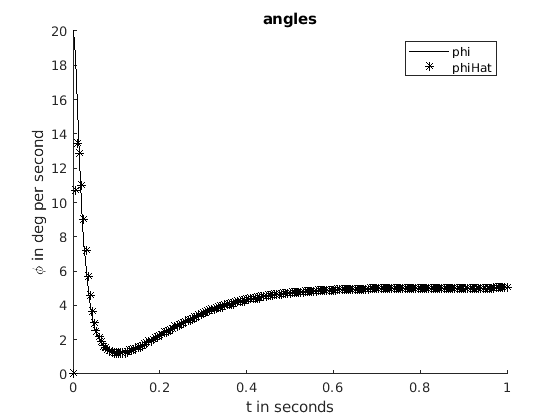

figure(); 
figTitle= "angles";
title(figTitle);
hold on;
plot(tSim, xSim(:, 1), "Color", "black");
plot(tSim, xhatSim(:, 1), "*", "Color", "black");
legend('phi', 'phiHat');
xlabel('t in seconds');
ylabel('\phi in deg per second');
hold off; 

Plot angles, simulated and observed.

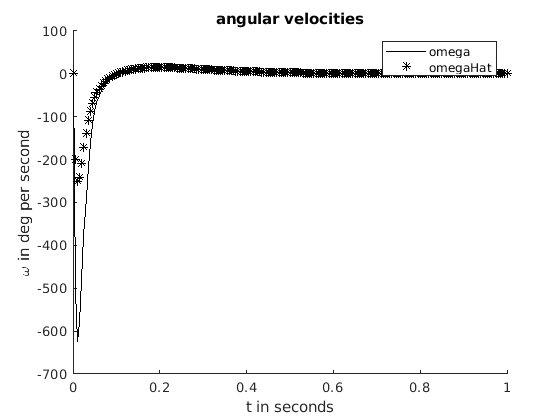

figure(); 
figTitle= "angular velocities";
title(figTitle);
hold on;
plot(tSim, xSim(:, 2), "Color", "black");
plot(tSim, xhatSim(:, 2), "*", "Color", "black");
xlabel('t in seconds');
ylabel('\omega in deg per second');
legend('omega', 'omegaHat')
hold off; 

## Export results to files, for use with other live scripts

identifyTransferFunctionContinuousTimeResults.continuousTimeTransferFunction= continuousTimeTransferFunction;
identifyTransferFunctionContinuousTimeResults.continuousTimeStateSpaceSys= continuousTimeStateSpaceSys;
identifyTransferFunctionContinuousTimeResults.delta_t= delta_t;
identifyTransferFunctionContinuousTimeResults.uStep= uStep;
identifyTransferFunctionContinuousTimeResults.tData= tData;
identifyTransferFunctionContinuousTimeResults.yData= yData; 
save("identifyTransferFunctionContinuousTimeResults.mat", 'identifyTransferFunctionContinuousTimeResults');

## Export matrices of the continuous-time state space system for use in Maple

Remember A and B suffice, since C and D are the same for the continuous-time and the corresponding discrete-time system. 

A= continuousTimeStateSpaceSys.A; % saveas command does not accept struct elements
B= continuousTimeStateSpaceSys.B;
C= continuousTimeStateSpaceSys.C;
D= continuousTimeStateSpaceSys.D;
save('matlabToMaple/A.txt', 'A', '-ascii');
save('matlabToMaple/B.txt', 'B', '-ascii');
save('matlabToMaple/C.txt', 'C', '-ascii');
save('matlabToMaple/D.txt', 'D', '-ascii');
save('matlabToMaple/delta_t.txt', 'delta_t', '-ascii')